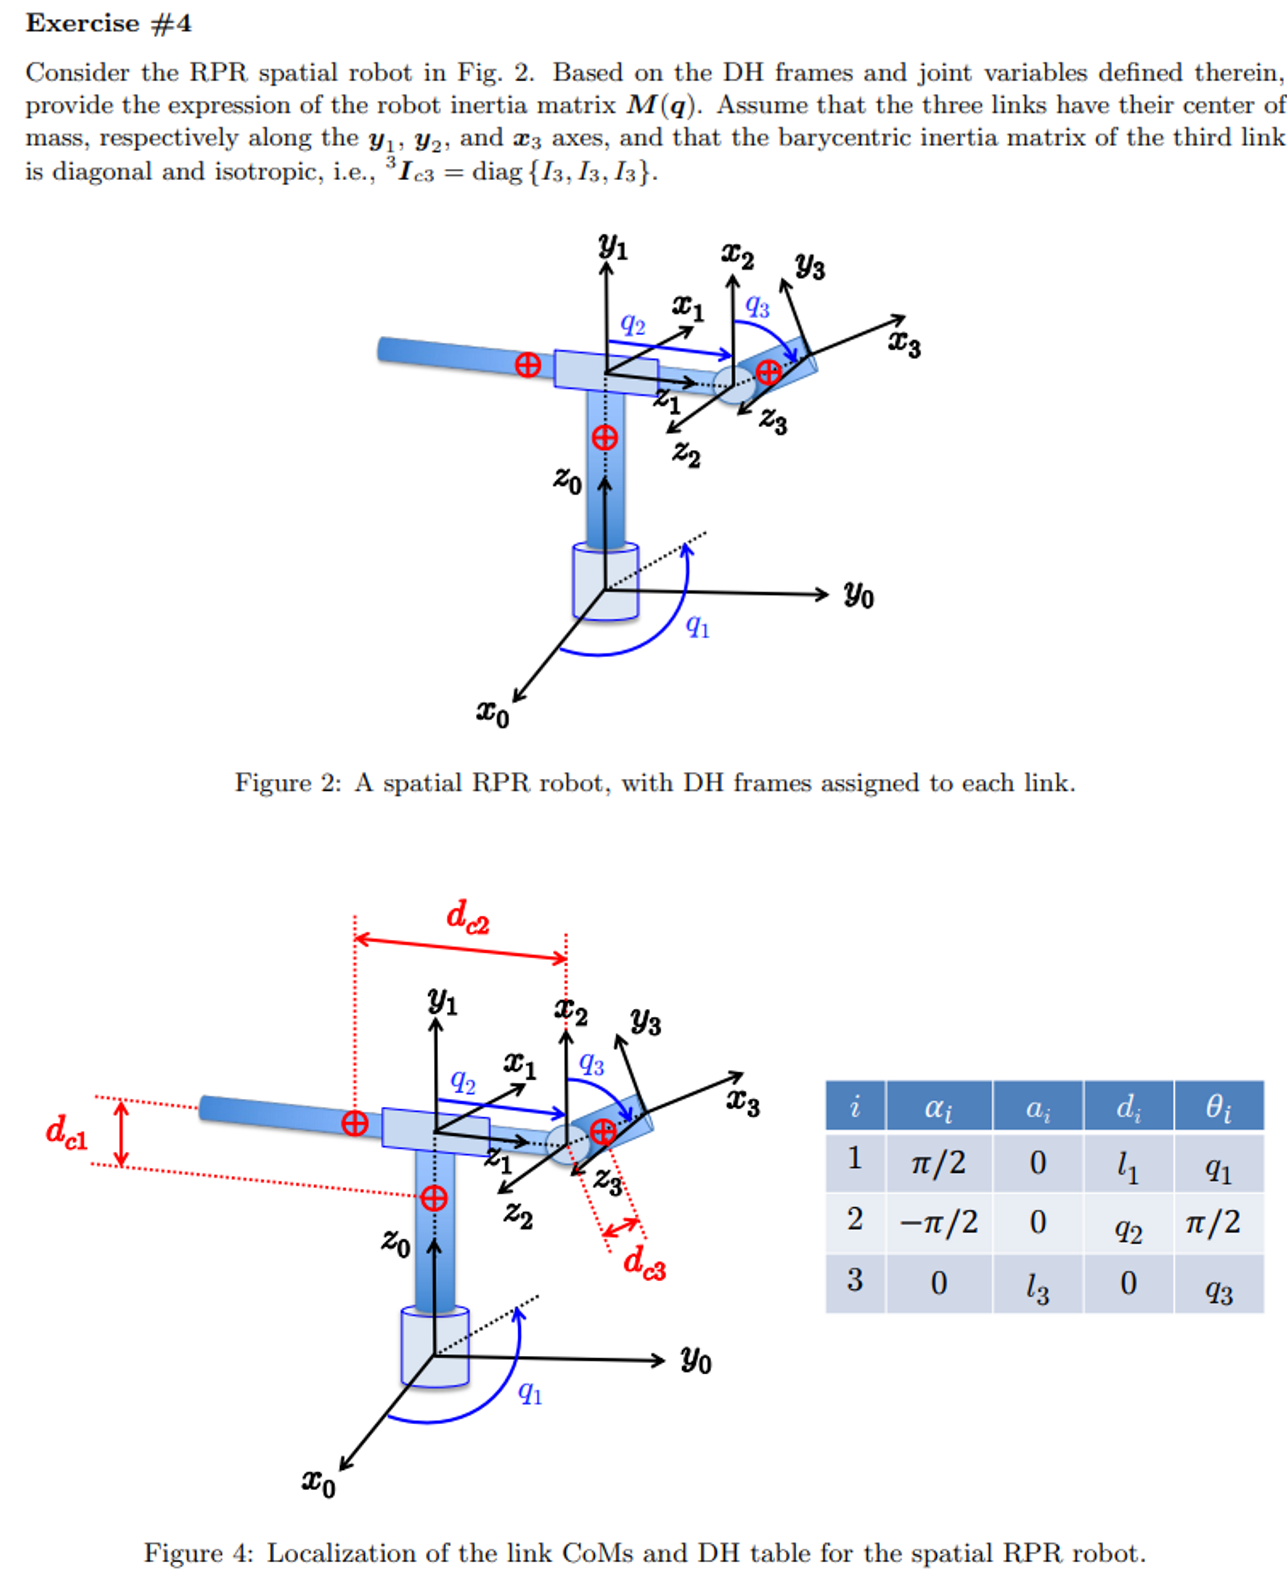

%es 1 PRR robot polar
clear all

n=3; 

syms q l dc m dq ddq [n 1] real

q = [q1; q2; q3];


q = [q1; q2; q3];
%dq = [dq1; dq2; dq3]; to define later
ddq = [ddq1; ddq2; ddq3];

%DH parameters
alpha = [(sym(pi)/2), -(sym(pi)/2), 0]; %IMPORTANT to make pi symbolic
a = [0, 0, l3];
d = [l1, q2, 0];
theta = [q1, (sym(pi)/2), q3];

A = cell(1, n);
A_tot = eye(4);


for i = 1:n
    alphai = alpha(i);
    ai = a(i);
    di = d(i);
    thetai = theta(i);

    A{i} =  [cos(thetai), -sin(thetai)*cos(alphai), sin(thetai)*sin(alphai), ai*cos(thetai);
            sin(thetai), cos(thetai)*cos(alphai), -cos(thetai)*sin(alphai), ai*sin(thetai);
            0, sin(alphai), cos(alphai), di;
            0, 0, 0, 1];

    %complete DH matrix for the robot

    A_tot = simplify(A_tot * A{i}); 

end 

%extracting from the homogeneous matrices the rotation matrices and
%positions for each joint

R1 = A{1}(1:3,1:3);
p1 = A{1}(1:3,4);

R2 = A{2}(1:3,1:3); 
p2 = A{2}(1:3,4);

R3 = A{3}(1:3,1:3); 
p3 = A{3}(1:3,4);

disp("Rotation matrices")

Rotation matrices


disp(R1)

$$\left(\begin{array}{ccc} \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right)\\ \sin\left(q_{1}\right) & 0 & -\cos\left(q_{1}\right)\\ 0 & 1 & 0 \end{array}\right)$$

disp(R2)

$$\left(\begin{array}{ccc} 0 & 0 & -1\\ 1 & 0 & 0\\ 0 & -1 & 0 \end{array}\right)$$

disp(R3)

$$\left(\begin{array}{ccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


disp("Origin's position in RFi-1")

Origin's position in RFi-1




disp(p1)

$$\left(\begin{array}{c} 0\\ 0\\ l_{1} \end{array}\right)$$

disp(p2)

$$\left(\begin{array}{c} 0\\ 0\\ q_{2} \end{array}\right)$$

disp(p3)

$$\left(\begin{array}{c} l_{3}\,\cos\left(q_{3}\right)\\ l_{3}\,\sin\left(q_{3}\right)\\ 0 \end{array}\right)$$


%position vectors from origin i-1 to origin i in frame i
% ip = i-1Ri' * i-1p !!! i am doing this computation here
% i-1p = i-1Ri * ip

r01 = simplify(R1'*p1);
r12 = simplify(R2'*p2);
r23 = simplify(R3'*p3);

disp("Position vectors from origin i-1 to origin i in frame i")

Position vectors from origin i-1 to origin i in frame i





disp(r01)

$$\left(\begin{array}{c} 0\\ l_{1}\\ 0 \end{array}\right)$$

disp(r12)

$$\left(\begin{array}{c} 0\\ -q_{2}\\ 0 \end{array}\right)$$

disp(r23)

$$\left(\begin{array}{c} l_{3}\\ 0\\ 0 \end{array}\right)$$



%!!!CoM position vector is the vector from the origin of frame i to the CMi
% expressed in frame i
%in this case we assume it to be in the kinematic axis of each link
%if we define di as the distance between origin of frame i to CMi

%Understanding the link axis from DH parameters:
%if alpha_i = 0 the link extends on x-axis of frame i
%if alpha_i = pi/2 the link extends on y_axis of frame i
%if alpha_i = pi the link extends on -x-axis of frame i

% to find the link lengths look at the ai parameter:
%in this case a2 and a3 are our link lengths 

%we define d1 d2 d3 as the distance between origin i-1 and position of CoMi

rc_1 = [0; dc1; 0];

rc_2= [0; dc2; 0];

rc_3= [dc3; 0; 0];


disp("Position vectors in frame i for CoMi for each link")

Position vectors in frame i for CoMi for each link


disp(rc_1)

$$\left(\begin{array}{c} 0\\ {\mathrm{dc}}_{1}\\ 0 \end{array}\right)$$

disp(rc_2)

$$\left(\begin{array}{c} 0\\ {\mathrm{dc}}_{2}\\ 0 \end{array}\right)$$

disp(rc_3)

$$\left(\begin{array}{c} {\mathrm{dc}}_{3}\\ 0\\ 0 \end{array}\right)$$


disp("CoM position vectors in RF0")

CoM position vectors in RF0





% ip = i-1Ri' * i-1p 
% i-1p = i-1Ri * ip !!i am doing this computation here

rc_01 = simplify((R1*rc_1) + p1);
disp(rc_01)

$$\left(\begin{array}{c} 0\\ 0\\ {\mathrm{dc}}_{1}+l_{1} \end{array}\right)$$

rc_02 = simplify((R1* (R2*rc_2)) + R1*p2 + p1);
disp(rc_02)

$$\left(\begin{array}{c} -\sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{2}-q_{2}\right)\\ \cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{2}-q_{2}\right)\\ l_{1} \end{array}\right)$$

rc_03 = simplify((R1*(R2*(R3*rc_3))) + R1*(R2*p3) + R1*p2 + p1);
disp(rc_03)

$$\left(\begin{array}{c} -\sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{3}\,\sin\left(q_{3}\right)-q_{2}+l_{3}\,\sin\left(q_{3}\right)\right)\\ \cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{3}\,\sin\left(q_{3}\right)-q_{2}+l_{3}\,\sin\left(q_{3}\right)\right)\\ l_{1}+{\mathrm{dc}}_{3}\,\cos\left(q_{3}\right)+l_{3}\,\cos\left(q_{3}\right) \end{array}\right)$$



disp("MOVING FRAMES ALGORITHM")

MOVING FRAMES ALGORITHM




%-------MOVING FRAMES ALGORITHM-------


%Defining the sigma as: 0 if revolute joint, 1 if prismatic
s1 = 0;
s2 = 1;
s3 = 0;


%if the robot were planar  
%syms Ic1 Ic2 Ic3 real

%the robot is polar so
syms Ic_xx_1 Ic_yy_1 Ic_zz_1 Ic_xx_2 Ic_yy_2 Ic_zz_2 Ic_xx_3 Ic_yy_3 Ic_zz_3 real
Ic1 = diag([Ic_xx_1, Ic_yy_1, Ic_zz_1]);
Ic2 = diag([Ic_xx_2, Ic_yy_2, Ic_zz_2]);
Ic3 = diag([Ic_xx_3, Ic_yy_3, Ic_zz_3]);


T = cell(1, n);
w = cell(1, n);
v = cell(1, n);
vc = cell(1, n);

%set up to change if we have more joints
s={s1, s2, s3};
dq = {dq1, dq2, dq3};

R = {R1, R2, R3};
r = {r01, r12, r23};
rc = {rc_1, rc_2, rc_3};
m = {m1, m2, m3};
Ic = {Ic1, Ic2, Ic3};


for i = 1:n
    Ri = R{i};
    si = s{i};
    dqi = dq{i};
    ri = r{i};
    rci  = rc{i};
    mi = m{i};
    Ici = Ic{i};

    %initialization if first frame = 0
    if i == 1
        wi_1 = 0;
        vi_1 = 0;
    else
        wi_1 = w(i-1);
        vi_1 = v(i-1);
    end

    w{i} = simplify(transpose(Ri)*(wi_1+(1-si)*dqi*[0; 0; 1]));

    wi = w{i};

    v{i} = simplify(transpose(Ri)*(vi_1+(si)*dqi*[0; 0; 1]) + cross(wi,ri));

    vi = v{i};

    vc{i} = simplify(vi + cross(wi,rci));

    vci = vc{i};

    T{i} = simplify((1/2)*mi*transpose(vci)*vci + (1/2)*transpose(wi)*Ici*wi);
    
end 


for i = 1:n
    disp("Joint")
    disp(i)
    disp("Angular velocity:")
    disp(w{i})
    disp("Linear velocity:")
    disp(v{i})
    disp("CoM linear velocity:")
    disp(vc{i})
    disp("Kinetic energy:")
    disp(T{i})
end

Joint


     1



Angular velocity:


$$\left(\begin{array}{c} 0\\ {\mathrm{dq}}_{1}\\ 0 \end{array}\right)$$

Linear velocity:


$$\left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

CoM linear velocity:


$$\left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

Kinetic energy:


$$\frac{{\mathrm{Ic}}_{\mathrm{yy},1}\,{{\mathrm{dq}}_{1}}^{2}}{2}$$

Joint


     2



Angular velocity:


$$\left(\begin{array}{c} {\mathrm{dq}}_{1}\\ 0\\ 0 \end{array}\right)$$

Linear velocity:


$$\left(\begin{array}{c} 0\\ -{\mathrm{dq}}_{2}\\ -{\mathrm{dq}}_{1}\,q_{2} \end{array}\right)$$

CoM linear velocity:


$$\left(\begin{array}{c} 0\\ -{\mathrm{dq}}_{2}\\ {\mathrm{dq}}_{1}\,\left({\mathrm{dc}}_{2}-q_{2}\right) \end{array}\right)$$

Kinetic energy:


$$\frac{{\mathrm{Ic}}_{\mathrm{xx},2}\,{{\mathrm{dq}}_{1}}^{2}}{2}+\frac{{{\mathrm{dq}}_{2}}^{2}\,m_{2}}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,m_{2}\,{\left({\mathrm{dc}}_{2}-q_{2}\right)}^{2}}{2}$$

Joint


     3



Angular velocity:


$$\left(\begin{array}{c} {\mathrm{dq}}_{1}\,\cos\left(q_{3}\right)\\ -{\mathrm{dq}}_{1}\,\sin\left(q_{3}\right)\\ {\mathrm{dq}}_{3} \end{array}\right)$$

Linear velocity:


$$\left(\begin{array}{c} -{\mathrm{dq}}_{2}\,\sin\left(q_{3}\right)\\ {\mathrm{dq}}_{3}\,l_{3}-{\mathrm{dq}}_{2}\,\cos\left(q_{3}\right)\\ -{\mathrm{dq}}_{1}\,\left(q_{2}-l_{3}\,\sin\left(q_{3}\right)\right) \end{array}\right)$$

CoM linear velocity:


$$\left(\begin{array}{c} -{\mathrm{dq}}_{2}\,\sin\left(q_{3}\right)\\ {\mathrm{dc}}_{3}\,{\mathrm{dq}}_{3}+{\mathrm{dq}}_{3}\,l_{3}-{\mathrm{dq}}_{2}\,\cos\left(q_{3}\right)\\ {\mathrm{dc}}_{3}\,{\mathrm{dq}}_{1}\,\sin\left(q_{3}\right)-{\mathrm{dq}}_{1}\,\left(q_{2}-l_{3}\,\sin\left(q_{3}\right)\right) \end{array}\right)$$

Kinetic energy:


$$\frac{{\mathrm{Ic}}_{\mathrm{zz},3}\,{{\mathrm{dq}}_{3}}^{2}}{2}+\frac{m_{3}\,{\left({\mathrm{dc}}_{3}\,{\mathrm{dq}}_{3}+{\mathrm{dq}}_{3}\,l_{3}-{\mathrm{dq}}_{2}\,\cos\left(q_{3}\right)\right)}^{2}}{2}+\frac{m_{3}\,{\left({\mathrm{dq}}_{1}\,\left(q_{2}-l_{3}\,\sin\left(q_{3}\right)\right)-{\mathrm{dc}}_{3}\,{\mathrm{dq}}_{1}\,\sin\left(q_{3}\right)\right)}^{2}}{2}+\frac{{\mathrm{Ic}}_{\mathrm{xx},3}\,{{\mathrm{dq}}_{1}}^{2}\,{\cos\left(q_{3}\right)}^{2}}{2}+\frac{{\mathrm{Ic}}_{\mathrm{yy},3}\,{{\mathrm{dq}}_{1}}^{2}\,{\sin\left(q_{3}\right)}^{2}}{2}+\frac{{{\mathrm{dq}}_{2}}^{2}\,m_{3}\,{\sin\left(q_{3}\right)}^{2}}{2}$$


disp("Total kinetic energy")

Total kinetic energy



%Total kinetic Energy of the Robot 
T_tot = T{1} +T{2} +T{3};
T_tot=simplify(T_tot);
T_tot=collect(T_tot,dq1^2);
T_tot=collect(T_tot,dq2^2);
T_tot=collect(T_tot,dq3^3);
disp(T_tot)

$$\left(\frac{{\mathrm{Ic}}_{\mathrm{xx},2}}{2}+\frac{{\mathrm{Ic}}_{\mathrm{yy},1}}{2}+\frac{m_{2}\,{\left({\mathrm{dc}}_{2}-q_{2}\right)}^{2}}{2}+\frac{{\mathrm{Ic}}_{\mathrm{xx},3}\,{\cos\left(q_{3}\right)}^{2}}{2}+\frac{{\mathrm{Ic}}_{\mathrm{yy},3}\,{\sin\left(q_{3}\right)}^{2}}{2}\right)\,{{\mathrm{dq}}_{1}}^{2}+\left(\frac{m_{3}\,{\sin\left(q_{3}\right)}^{2}}{2}+\frac{m_{2}}{2}\right)\,{{\mathrm{dq}}_{2}}^{2}+\frac{{\mathrm{Ic}}_{\mathrm{zz},3}\,{{\mathrm{dq}}_{3}}^{2}}{2}+\frac{m_{3}\,{\left({\mathrm{dc}}_{3}\,{\mathrm{dq}}_{3}+{\mathrm{dq}}_{3}\,l_{3}-{\mathrm{dq}}_{2}\,\cos\left(q_{3}\right)\right)}^{2}}{2}+\frac{m_{3}\,{\left({\mathrm{dq}}_{1}\,\left(q_{2}-l_{3}\,\sin\left(q_{3}\right)\right)-{\mathrm{dc}}_{3}\,{\mathrm{dq}}_{1}\,\sin\left(q_{3}\right)\right)}^{2}}{2}$$


% Inertia Matrix
M11 = diff(diff(T_tot, dq1), dq1);
M12 = diff(diff(T_tot, dq1), dq2);
M13 = diff(diff(T_tot, dq1), dq3);

M21 = diff(diff(T_tot, dq2), dq1);
M22 = diff(diff(T_tot, dq2), dq2);
M23 = diff(diff(T_tot, dq2), dq3);

M31 = diff(diff(T_tot, dq3), dq1);
M32 = diff(diff(T_tot, dq3), dq2);
M33 = diff(diff(T_tot, dq3), dq3);

M = simplify([M11, M12, M13; M21, M22, M23; M31, M32, M33],Steps=1000)

$$M = \begin{array}{l} \left(\begin{array}{ccc} {\mathrm{Ic}}_{\mathrm{xx},2}+{\mathrm{Ic}}_{\mathrm{yy},1}-{\mathrm{Ic}}_{\mathrm{xx},3}\,\left({\sin\left(q_{3}\right)}^{2}-1\right)+m_{3}\,{\left({\mathrm{dc}}_{3}\,\sin\left(q_{3}\right)-q_{2}+l_{3}\,\sin\left(q_{3}\right)\right)}^{2}+m_{2}\,{\left({\mathrm{dc}}_{2}-q_{2}\right)}^{2}+{\mathrm{Ic}}_{\mathrm{yy},3}\,{\sin\left(q_{3}\right)}^{2} & 0 & 0\\ 0 & m_{2}+m_{3} & \sigma_{1}\\ 0 & \sigma_{1} & {\mathrm{Ic}}_{\mathrm{zz},3}+m_{3}\,{\left({\mathrm{dc}}_{3}+l_{3}\right)}^{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-m_{3}\,\cos\left(q_{3}\right)\,\left({\mathrm{dc}}_{3}+l_{3}\right) \end{array}$$